# **Monte-Carlo and Gauss-Legendre Numerical Integration Methods for 1- to 3-D Functions**

**Authors**: Jiayi Lai, Dorothy Ma, Marc-Antoine Nadeau, Haochen Xu

## Gauss-Legendre Integration Test: 

### Function #1 Gauss-Legendre

% Define test function for 1D, 2D & 3D case
fun1 = @(x) (2*pi).^(-1/2)* exp(0.5*(-x.^2));
fun2 = @(x, y) 1 / (2 * pi) * exp(-0.5 * (x.^2 + y.^2));
fun3 = @(x,y,z) (2*pi).^(-3/2)*exp(0.5*(-x.^2-y.^2-z.^2));

% Define the limits of integration for each dimension
a_x = -3; b_x = 3; % Limits for x
a_y = -3; b_y = 3; % Limits for y
a_z = -3; b_z = 3; % Limits for y

% 1D Integral 
value1 = integral(fun1,a_x,b_x)

value1 = 0.9973

tic
value_GL1 = integral_GL1(fun1,8, a_x,b_x)               % Calculate 1D integral using Gauss-Legendre Quadrature

value_GL1 = 0.9973

toc                                                     % Time taken for compute 1D integral using Gauss-Legendre Quadrature

Elapsed time is 0.001584 seconds.



absoluteError1D = abs ((value_GL1-value1) / value1 )    % Calculate Absolute Error of the 1D integral using Gauss-Legendre Quadrature

absoluteError1D = 3.1923e-05

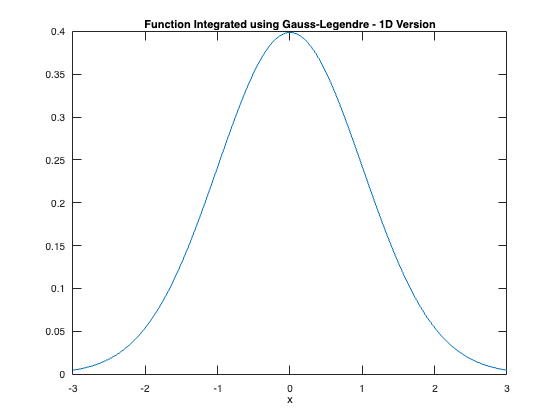


plot_1D( fun1, a_x,b_x)                                 % Plot func1 - 1D Case                                          


% 2D Integral
value2 = integral2(fun2,a_x,b_x,a_y,b_y)                

value2 = 0.9946

tic
value_GL2 = integral_GL2(fun2,[8,8], a_x,b_x,a_y,b_y)   % Calculate 2D integral using Gauss-Legendre Quadrature

value_GL2 = 0.9945

toc                                                     % Time taken for compute 2D integral using Gauss-Legendre Quadrature

Elapsed time is 0.006080 seconds.


absolutError2D = abs ((value_GL2-value2) / value2)      % Calculate Absolute Error of the 2D integral using Gauss-Legendre Quadrature 

absolutError2D = 6.3845e-05

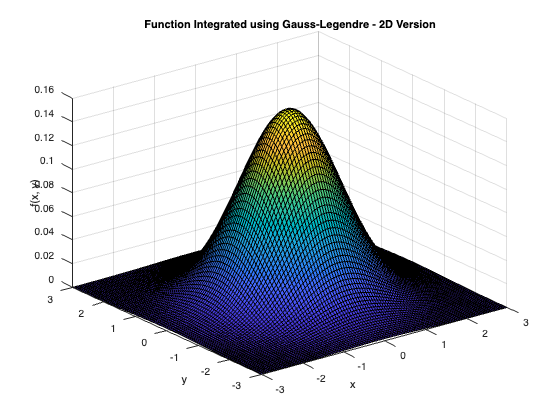


plot_2D(fun2, a_x, b_x, a_y, b_y)                       % Plot func1 - 2D Case



% 3D Integral
value3 = integral3(fun3, a_x, b_x, a_y, b_y, a_z, b_z)  

value3 = 0.9919

tic
value_GL3 = integral_GL3(fun3,[8,8,8], a_x, b_x, a_y, b_y, a_z, b_z) % Calculate 3D integral using Gauss-Legendre Quadrature

value_GL3 = 0.9918

toc                                                                  % Time taken for compute 3D integral using Gauss-Legendre Quadrature

Elapsed time is 0.010011 seconds.


absolutError3D = abs (( value_GL3-value3 ) / value3)                 % Calculate Absolute Error of the 3D integral using Gauss-Legendre Quadrature 

absolutError3D = 9.5765e-05

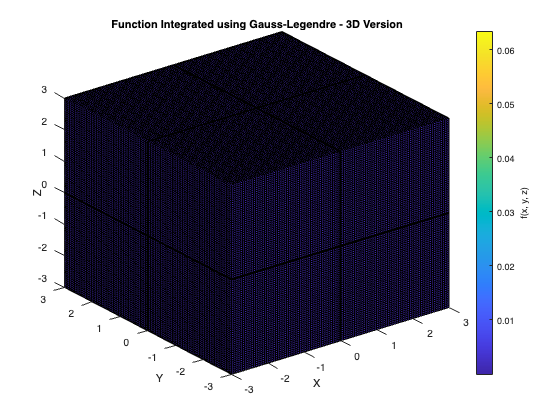

plot_3D( fun3, a_x, b_x, a_y, b_y, a_z, b_z)                         % Plot func1 - 3D Case

### Function #2 Gauss-Legendre

% Define test function for 1D,2D 3D case
fun1 = @(x) abs(4*x-2);
fun2 = @(x, y) abs(4*x-2).*abs(4*y-2);
fun3 = @(x, y,z) abs(4*x-2).*abs(4*y-2).*abs(4*z-2);

% Define the limits of integration for each dimension
a_x = 0; b_x = 1; % Limits for x
a_y = 0; b_y = 1; % Limits for y
a_z = 0; b_z = 1; % Limits for y



% 1D Integral 
value1 = integral(fun1,a_x,b_x)

value1 = 1

tic
value_GL1 = integral_GL1(fun1,8, a_x,b_x)               % Calculate 1D integral using Gauss-Legendre Quadrature

value_GL1 = 1.0115

toc                                                     % Time taken for compute 1D integral using Gauss-Legendre Quadrature

Elapsed time is 0.001610 seconds.



absoluteError1D = abs ((value_GL1-value1) / value1 )    % Calculate Absolute Error of the 1D integral using Gauss-Legendre Quadrature

absoluteError1D = 0.0115

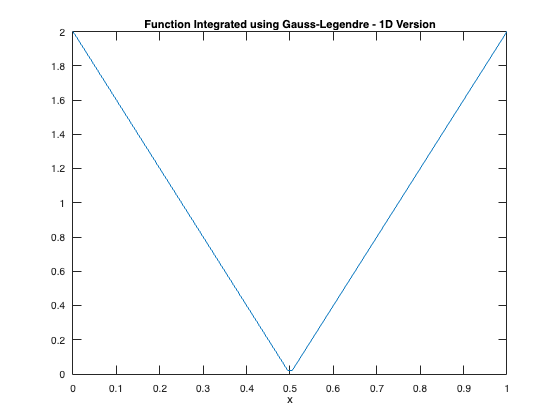


plot_1D( fun1, a_x,b_x)                                 % Plot func1 - 1D Case                                          


% 2D Integral
value2 = integral2(fun2,a_x,b_x,a_y,b_y)                

value2 = 1.0000

tic
value_GL2 = integral_GL2(fun2,[8,8], a_x,b_x,a_y,b_y)   % Calculate 2D integral using Gauss-Legendre Quadrature

value_GL2 = 1.0232

toc                                                     % Time taken for compute 2D integral using Gauss-Legendre Quadrature

Elapsed time is 0.003053 seconds.


absolutError2D = abs ((value_GL2-value2) / value2)      % Calculate Absolute Error of the 2D integral using Gauss-Legendre Quadrature 

absolutError2D = 0.0232

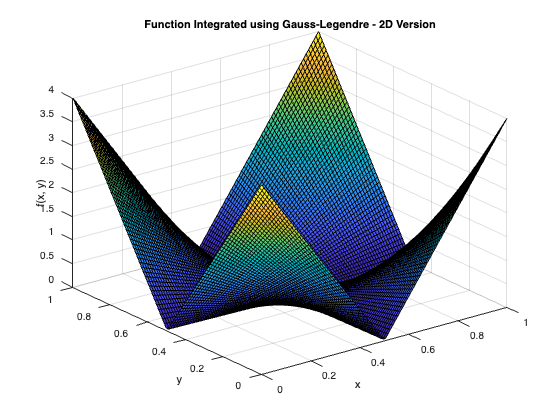


plot_2D(fun2, a_x, b_x, a_y, b_y)                       % Plot func1 - 2D Case



% 3D Integral
value3 = integral3(fun3, a_x, b_x, a_y, b_y, a_z, b_z)  

value3 = 1.0000

tic
value_GL3 = integral_GL3(fun3,[8,8,8], a_x, b_x, a_y, b_y, a_z, b_z) % Calculate 3D integral using Gauss-Legendre Quadrature

value_GL3 = 1.0350

toc                                                                  % Time taken for compute 3D integral using Gauss-Legendre Quadrature

Elapsed time is 0.010868 seconds.


absolutError3D = abs (( value_GL3-value3 ) / value3)                 % Calculate Absolute Error of the 3D integral using Gauss-Legendre Quadrature 

absolutError3D = 0.0350

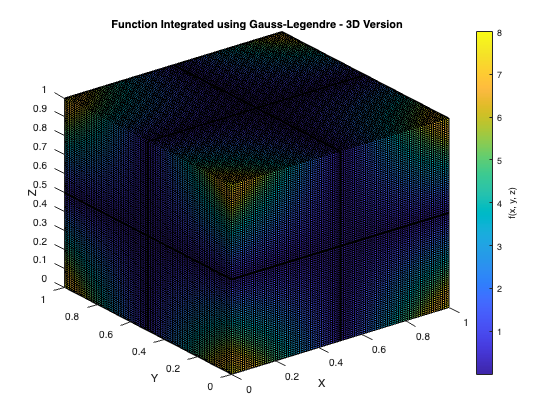

plot_3D( fun3, a_x, b_x, a_y, b_y, a_z, b_z)                         % Plot func1 - 3D Case

### Function #3 Gauss-Legendre

% Define the constants used in functions
a = 5;
u = 0.5;

% Define test function for 1D, 2D & 3D case
fun1 = @(x) 1 ./ (a.^(-2) + (x - u).^2);
fun2 = @(x, y) 1 ./ (a.^(-2) + (x - u).^2) .* 1 ./ (a.^(-2) + (y - u).^2);
fun3 = @(x, y, z) 1 ./ (a.^(-2) + (x - u).^2) .* 1 ./ (a.^(-2) + (y - u).^2) .* 1 ./ (a.^(-2) + (z - u).^2);



% Define the limits of integration for each dimension
a_x = 0; b_x = 1; % Limits for x
a_y = 0; b_y = 1; % Limits for y
a_z = 0; b_z = 1; % Limits for y



% 1D Integral 
value1 = integral(fun1,a_x,b_x)

value1 = 11.9029

tic
value_GL1 = integral_GL1(fun1,8, a_x,b_x)               % Calculate 1D integral using Gauss-Legendre Quadrature

value_GL1 = 11.8620

toc                                                     % Time taken for compute 1D integral using Gauss-Legendre Quadrature

Elapsed time is 0.001037 seconds.



absoluteError1D = abs ((value_GL1-value1) / value1 )    % Calculate Absolute Error of the 1D integral using Gauss-Legendre Quadrature

absoluteError1D = 0.0034

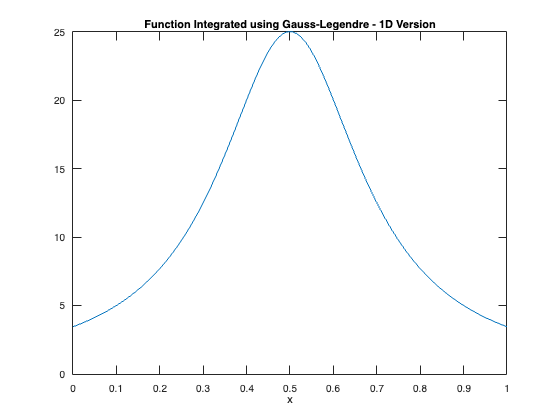


plot_1D( fun1, a_x,b_x)                                 % Plot func1 - 1D Case                                          


% 2D Integral
value2 = integral2(fun2,a_x,b_x,a_y,b_y)                

value2 = 141.6790

tic
value_GL2 = integral_GL2(fun2,[8,8], a_x,b_x,a_y,b_y)   % Calculate 2D integral using Gauss-Legendre Quadrature

value_GL2 = 140.7059

toc                                                     % Time taken for compute 2D integral using Gauss-Legendre Quadrature

Elapsed time is 0.003121 seconds.


absolutError2D = abs ((value_GL2-value2) / value2)      % Calculate Absolute Error of the 2D integral using Gauss-Legendre Quadrature 

absolutError2D = 0.0069

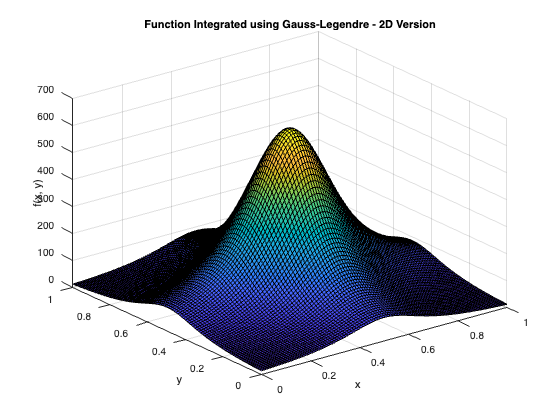


plot_2D(fun2, a_x, b_x, a_y, b_y)                       % Plot func1 - 2D Case



% 3D Integral
value3 = integral3(fun3, a_x, b_x, a_y, b_y, a_z, b_z)  

value3 = 1.6864e+03

tic
value_GL3 = integral_GL3(fun3,[8,8,8], a_x, b_x, a_y, b_y, a_z, b_z) % Calculate 3D integral using Gauss-Legendre Quadrature

value_GL3 = 1.6690e+03

toc                                                                  % Time taken for compute 3D integral using Gauss-Legendre Quadrature

Elapsed time is 0.009754 seconds.


absolutError3D = abs (( value_GL3-value3 ) / value3)                 % Calculate Absolute Error of the 3D integral using Gauss-Legendre Quadrature 

absolutError3D = 0.0103

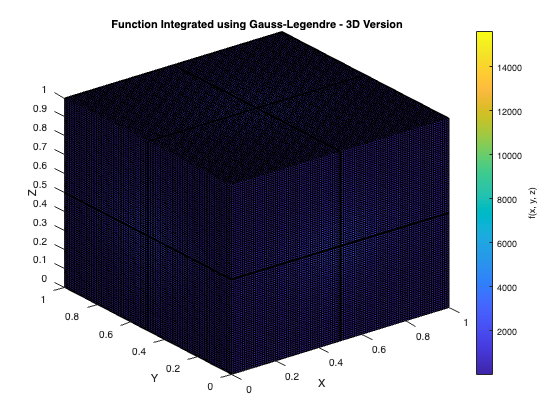

plot_3D( fun3, a_x, b_x, a_y, b_y, a_z, b_z)                         % Plot func1 - 3D Case

### Function #4 Gauss-Legendre

% Define the limits of integration for each dimension
a = 5;
u = 0.5;
% Define test function for 1D, 2D & 3D case
fun1 = @(x) cos(2.*pi.*u + a.*x);
fun2 = @(x, y) cos(2.*pi.*u + a.*x+a.*y);
fun3 = @(x, y, z) cos(2.*pi.*u + a.*x+a.*y+a.*z);



% Define the limits of integration for each dimension
a_x = 0; b_x = 1; % Limits for x
a_y = 0; b_y = 1; % Limits for y
a_z = 0; b_z = 1; % Limits for y


% 1D Integral 
value1 = integral(fun1,a_x,b_x)

value1 = 0.1918

tic
value_GL1 = integral_GL1(fun1,8, a_x,b_x)               % Calculate 1D integral using Gauss-Legendre Quadrature

value_GL1 = 0.1918

toc                                                     % Time taken for compute 1D integral using Gauss-Legendre Quadrature

Elapsed time is 0.001088 seconds.



absoluteError1D = abs ((value_GL1-value1) / value1 )    % Calculate Absolute Error of the 1D integral using Gauss-Legendre Quadrature

absoluteError1D = 9.9181e-12

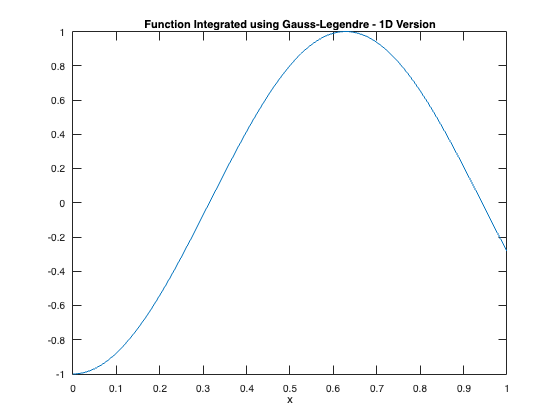


plot_1D( fun1, a_x,b_x)                                 % Plot func1 - 1D Case                                          


% 2D Integral
value2 = integral2(fun2,a_x,b_x,a_y,b_y)                

value2 = -0.0163

tic
value_GL2 = integral_GL2(fun2,[8,8], a_x,b_x,a_y,b_y)   % Calculate 2D integral using Gauss-Legendre Quadrature

value_GL2 = -0.0163

toc                                                     % Time taken for compute 2D integral using Gauss-Legendre Quadrature

Elapsed time is 0.003888 seconds.


absolutError2D = abs ((value_GL2-value2) / value2)      % Calculate Absolute Error of the 2D integral using Gauss-Legendre Quadrature 

absolutError2D = 2.6996e-09

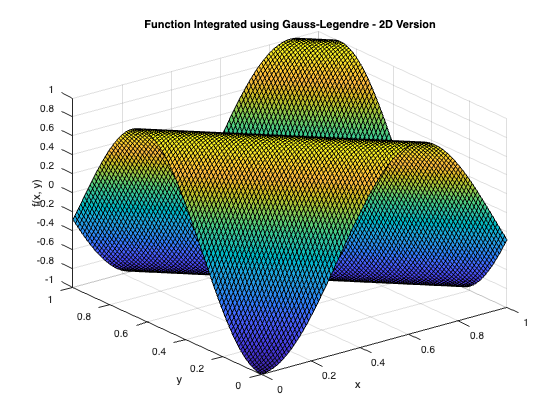


plot_2D(fun2, a_x, b_x, a_y, b_y)                       % Plot func1 - 2D Case



% 3D Integral
value3 = integral3(fun3, a_x, b_x, a_y, b_y, a_z, b_z)  

value3 = -0.0048

tic
value_GL3 = integral_GL3(fun3,[8,8,8], a_x, b_x, a_y, b_y, a_z, b_z) % Calculate 3D integral using Gauss-Legendre Quadrature

value_GL3 = -0.0048

toc                                                                  % Time taken for compute 3D integral using Gauss-Legendre Quadrature

Elapsed time is 0.009326 seconds.


absolutError3D = abs (( value_GL3-value3 ) / value3)                 % Calculate Absolute Error of the 3D integral using Gauss-Legendre Quadrature 

absolutError3D = 8.4939e-10

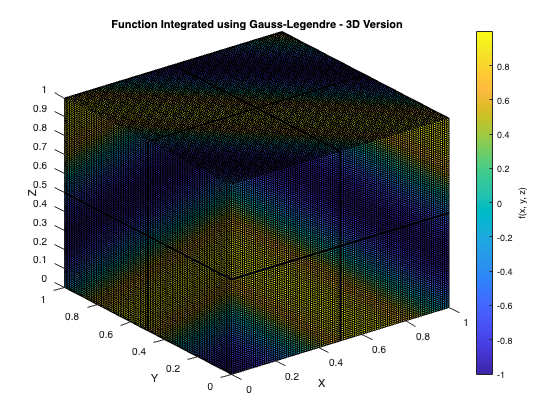

plot_3D( fun3, a_x, b_x, a_y, b_y, a_z, b_z)                         % Plot func1 - 3D Case

### Function #5 Gauss-Legendre

% Define the constant used in functions
a = 5;

% Define test function for 1D, 2D & 3D case
fun1 = @(x) (abs(4.*x-2)+a)./(1+a);
fun2 = @(x,y) (abs(4.*x-2)+a)./(1+a) .* (abs(4.*y-2)+a)./(1+a);
fun3 = @(x,y,z) (abs(4.*x-2)+a)./(1+a) .* (abs(4.*y-2)+a)./(1+a).* (abs(4.*z-2)+a)./(1+a);



% Define the limits of integration for each dimension
a_x = 0; b_x = 1; % Limits for x
a_y = 0; b_y = 1; % Limits for y
a_z = 0; b_z = 1; % Limits for y


% 1D Integral 
value1 = integral(fun1,a_x,b_x)

value1 = 1.0000

tic
value_GL1 = integral_GL1(fun1,8, a_x,b_x)               % Calculate 1D integral using Gauss-Legendre Quadrature

value_GL1 = 1.0019

toc                                                     % Time taken for compute 1D integral using Gauss-Legendre Quadrature

Elapsed time is 0.001280 seconds.



absoluteError1D = abs ((value_GL1-value1) / value1 )    % Calculate Absolute Error of the 1D integral using Gauss-Legendre Quadrature

absoluteError1D = 0.0019

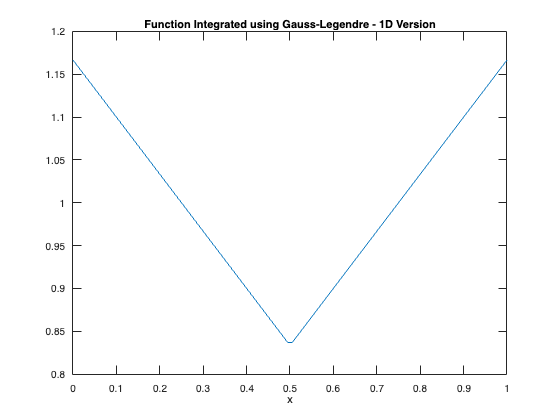


plot_1D( fun1, a_x,b_x)                                 % Plot func1 - 1D Case                                          


% 2D Integral
value2 = integral2(fun2,a_x,b_x,a_y,b_y)                

value2 = 1.0000

tic
value_GL2 = integral_GL2(fun2,[8,8], a_x,b_x,a_y,b_y)   % Calculate 2D integral using Gauss-Legendre Quadrature

value_GL2 = 1.0038

toc                                                     % Time taken for compute 2D integral using Gauss-Legendre Quadrature

Elapsed time is 0.003385 seconds.


absolutError2D = abs ((value_GL2-value2) / value2)      % Calculate Absolute Error of the 2D integral using Gauss-Legendre Quadrature 

absolutError2D = 0.0038

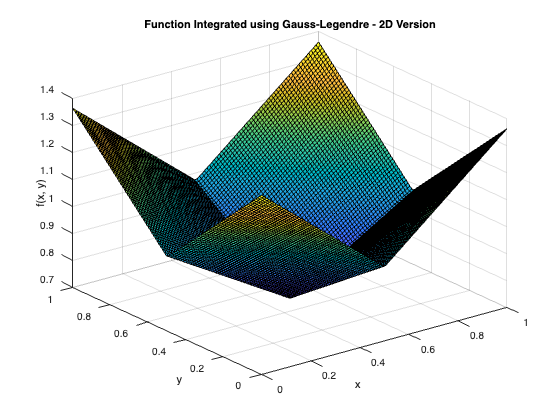


plot_2D(fun2, a_x, b_x, a_y, b_y)                       % Plot func1 - 2D Case



% 3D Integral
value3 = integral3(fun3, a_x, b_x, a_y, b_y, a_z, b_z)  

value3 = 1.0000

tic
value_GL3 = integral_GL3(fun3,[8,8,8], a_x, b_x, a_y, b_y, a_z, b_z) % Calculate 3D integral using Gauss-Legendre Quadrature

value_GL3 = 1.0058

toc                                                                  % Time taken for compute 3D integral using Gauss-Legendre Quadrature

Elapsed time is 0.008982 seconds.


absolutError3D = abs (( value_GL3-value3 ) / value3)                 % Calculate Absolute Error of the 3D integral using Gauss-Legendre Quadrature 

absolutError3D = 0.0058

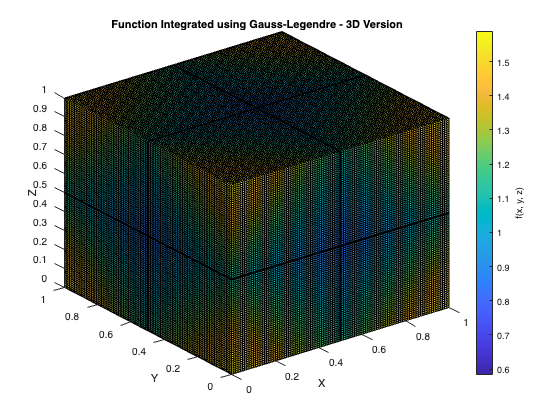

plot_3D( fun3, a_x, b_x, a_y, b_y, a_z, b_z)                         % Plot func1 - 3D Case

### **Function #6 **Gauss-Legendre

% Define the constant used in functions
a = 5;

% Define test function for 1D, 2D & 3D case
fun1 = @(x) (1+a*x).^(-2);
fun2 = @(x,y)  (1+a*x+a*y).^(-3);
fun3 = @(x,y,z) (1+a*x+a*y+a*z).^(-4);


% Define the limits of integration for each dimension
a_x = 0; b_x = 1; % Limits for x
a_y = 0; b_y = 1; % Limits for y
a_z = 0; b_z = 1; % Limits for y


% 1D Integral 
value1 = integral(fun1,a_x,b_x)

value1 = 0.1667

tic
value_GL1 = integral_GL1(fun1,8, a_x,b_x)               % Calculate 1D integral using Gauss-Legendre Quadrature

value_GL1 = 0.1667

toc                                                     % Time taken for compute 1D integral using Gauss-Legendre Quadrature

Elapsed time is 0.001219 seconds.



absoluteError1D = abs ((value_GL1-value1) / value1 )    % Calculate Absolute Error of the 1D integral using Gauss-Legendre Quadrature

absoluteError1D = 1.9877e-05

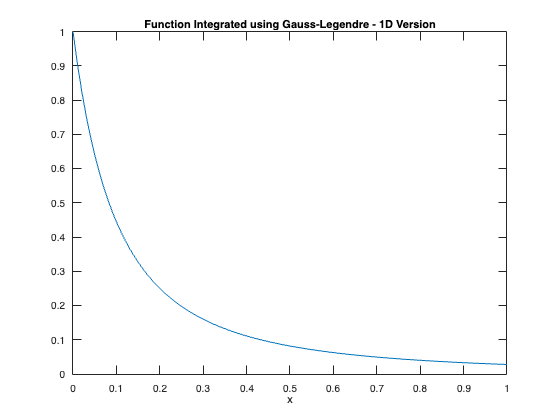


plot_1D( fun1, a_x,b_x)                                 % Plot func1 - 1D Case                                          


% 2D Integral
value2 = integral2(fun2,a_x,b_x,a_y,b_y)                

value2 = 0.0152

tic
value_GL2 = integral_GL2(fun2,[8,8], a_x,b_x,a_y,b_y)   % Calculate 2D integral using Gauss-Legendre Quadrature

value_GL2 = 0.0152

toc                                                     % Time taken for compute 2D integral using Gauss-Legendre Quadrature

Elapsed time is 0.003098 seconds.


absolutError2D = abs ((value_GL2-value2) / value2)      % Calculate Absolute Error of the 2D integral using Gauss-Legendre Quadrature 

absolutError2D = 4.3427e-05

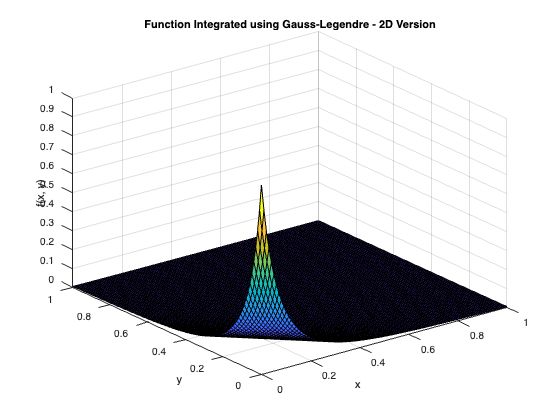


plot_2D(fun2, a_x, b_x, a_y, b_y)                       % Plot func1 - 2D Case



% 3D Integral
value3 = integral3(fun3, a_x, b_x, a_y, b_y, a_z, b_z)  

value3 = 9.4697e-04

tic
value_GL3 = integral_GL3(fun3,[8,8,8], a_x, b_x, a_y, b_y, a_z, b_z) % Calculate 3D integral using Gauss-Legendre Quadrature

value_GL3 = 9.4690e-04

toc                                                                  % Time taken for compute 3D integral using Gauss-Legendre Quadrature

Elapsed time is 0.008616 seconds.


absolutError3D = abs (( value_GL3-value3 ) / value3)                 % Calculate Absolute Error of the 3D integral using Gauss-Legendre Quadrature 

absolutError3D = 6.9120e-05

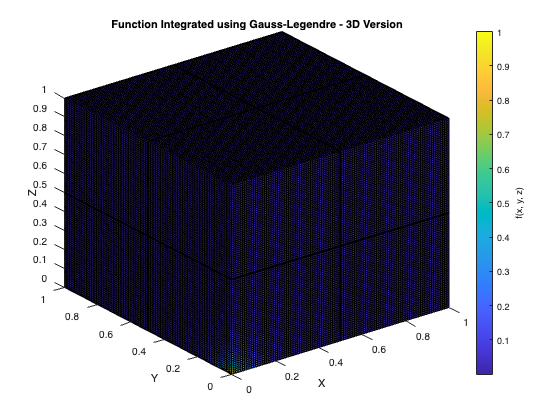

plot_3D( fun3, a_x, b_x, a_y, b_y, a_z, b_z)                         % Plot func1 - 3D Case

## **Smolyak Sparse Grid Points**

This algorithm was implemented to demonstrate the generation of a subset of the nodes. The Smolyak Sparse Grid is generated with Chebyshev polynomial instead of Legendre and only a select number of points based on the Smolyak conditions.

### **Smolyak Sparse Grid Points 2D**

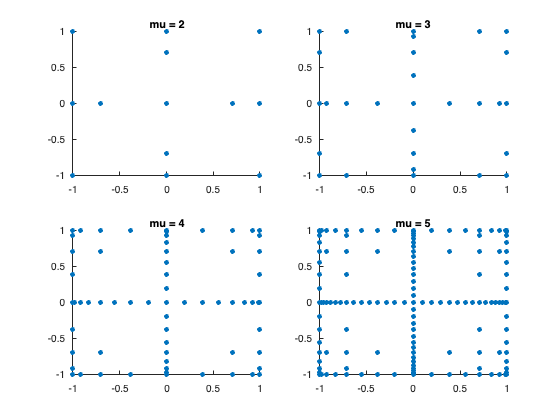

figure;
plotSmolyak2D();

### **Smolyak Sparse Grid Points 3D**

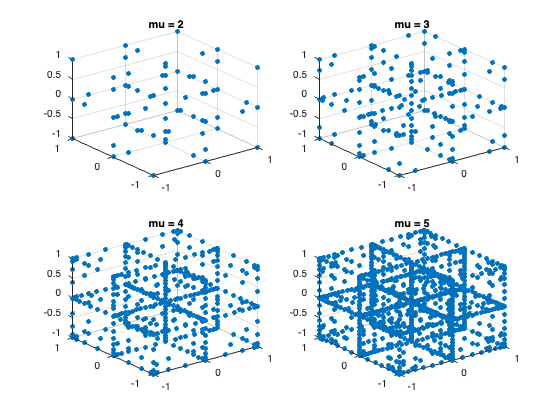

figure;
plotSmolyak3D();

## **Monte-Carlo** Integration Test: 

### **Function #1 Monte-Carlo**

% Define the limits of integration for each dimension
fun1 = @(x) (2*pi).^(-1/2)* exp(0.5*(-x.^2));
fun2 = @(x, y) 1 / (2 * pi) * exp(-0.5 * (x.^2 + y.^2));
fun3 = @(x,y,z) (2*pi).^(-3/2)*exp(0.5*(-x.^2-y.^2-z.^2));

% Define the limits of integration for each dimension,since for all 3
% variables are the same, we can only define the lower bound and upper
% bound.
a_l = -3;
b_u = 3;

%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral(fun1, a_l, b_u);
disp("matlab:"+matlab);

matlab:0.9973


% 1D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun1,a_l,b_u,N);
toc

Elapsed time is 0.240421 seconds.


disp("1D Monte Carlo Integral:"+monte_value);

1D Monte Carlo Integral:0.99873



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100; 
disp("Abserror:"+Abserror);

Abserror:0.1433


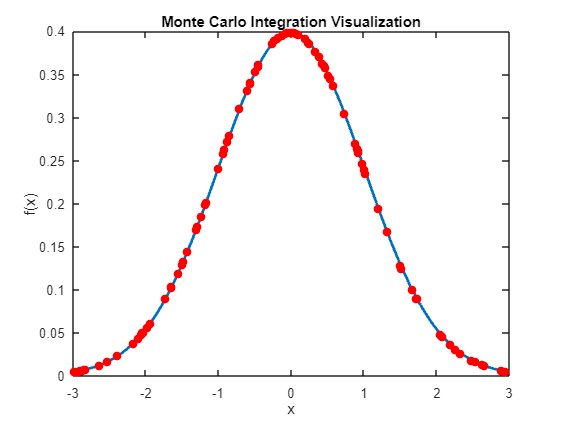


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_1D(fun1, a_l, b_u, N);

%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral2(fun2, a_l, b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:0.99461


% 2D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun2,a_l,b_u,N);
toc

Elapsed time is 0.111504 seconds.


disp("2D Monte Carlo Integral:"+monte_value);

2D Monte Carlo Integral:0.99514



%Calculate the absolute value of the relative error

Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.053953


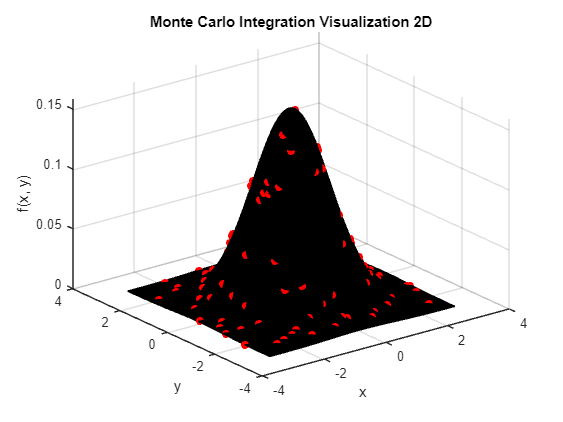

%In order to show the relationsip between each sample and the function
N=100;
monte_carlo_integration_visualization_2D(fun2, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral3(fun3, a_l, b_u,a_l,b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:0.99192



% 3D Monte-Carlo Integral
tic
monte_value=monte_carlo_integration(fun3,a_l,b_u,N);
toc

Elapsed time is 0.272592 seconds.


disp("3D Monte Carlo Integral:"+monte_value);

3D Monte Carlo Integral:0.9902



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.17414


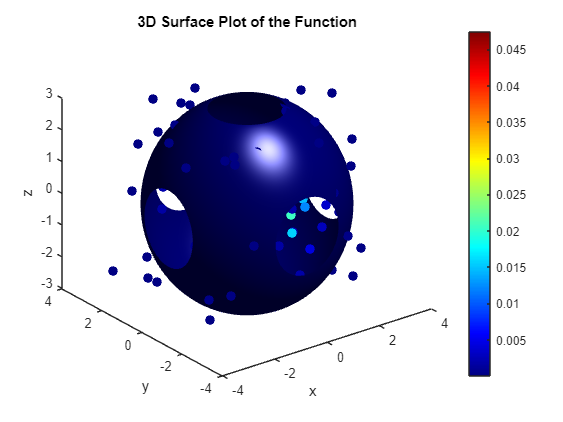

%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_3D(fun3, a_l, b_u, N);

### **Function #2 Monte-Carlo**

% Define the limits of integration for each dimension
fun1 = @(x) abs(4*x-2);
fun2 = @(x, y) abs(4*x-2).*abs(4*y-2);
fun3 = @(x, y,z) abs(4*x-2).*abs(4*y-2).*abs(4*z-2);

% Define the limits of integration for each dimension,since for all 3
% variables are the same, we can only define the lower bound and upper
% bound.
a_l = 0;
b_u = 1;

%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral(fun1, a_l, b_u);
disp("matlab:"+matlab);

matlab:1



% 1D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun1,a_l,b_u,N);
toc

Elapsed time is 0.064190 seconds.


disp("1D Monte Carlo Integral:"+monte_value);

1D Monte Carlo Integral:1



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100; 
disp("Abserror:"+Abserror);

Abserror:0.0019363


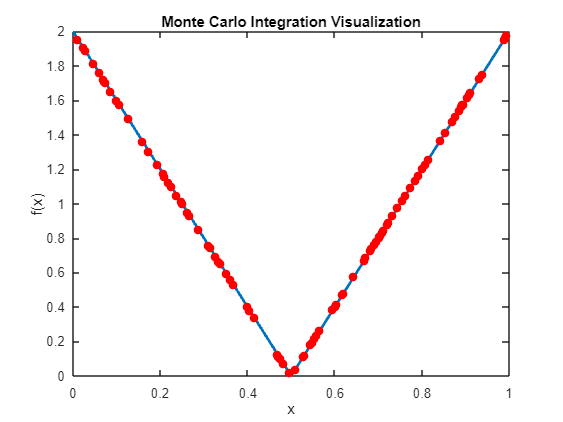


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_1D(fun1, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral2(fun2, a_l, b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:1



% 2D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun2,a_l,b_u,N);
toc

Elapsed time is 0.140716 seconds.


disp("2D Monte Carlo Integral:"+monte_value);

2D Monte Carlo Integral:0.99946



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.054199


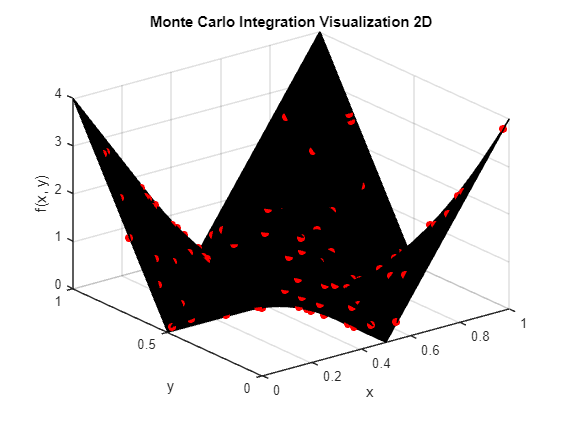


%In order to show the relationsip between each sample and the function
N=100;
monte_carlo_integration_visualization_2D(fun2, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral3(fun3, a_l, b_u,a_l,b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:1



% 3D Monte-Carlo Integral
tic
monte_value=monte_carlo_integration(fun3,a_l,b_u,N);
toc

Elapsed time is 0.132036 seconds.


disp("3D Monte Carlo Integral:"+monte_value);

3D Monte Carlo Integral:0.9984


%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.16026


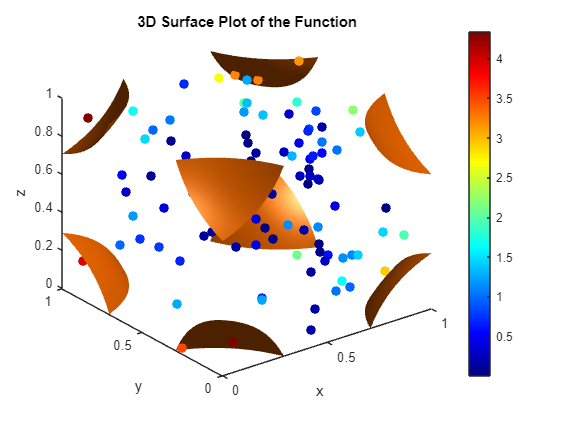


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_3D(fun3, a_l, b_u, N);

### **Function #3 Monte-Carlo**

% Define the limits of integration for each dimension
a = 5;
u = 0.5;

fun1 = @(x) 1 ./ (a.^(-2) + (x - u).^2);
fun2 = @(x, y) 1 ./ (a.^(-2) + (x - u).^2) .* 1 ./ (a.^(-2) + (y - u).^2);
fun3 = @(x, y, z) 1 ./ (a.^(-2) + (x - u).^2) .* 1 ./ (a.^(-2) + (y - u).^2) .* 1 ./ (a.^(-2) + (z - u).^2);


% Define the limits of integration for each dimension,since for all 3
% variables are the same, we can only define the lower bound and upper
% bound.
a_l = 0;
b_u = 1;

%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral(fun1, a_l, b_u);
disp("matlab:"+matlab);

matlab:11.9029



% 1D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun1,a_l,b_u,N);
toc

Elapsed time is 0.216759 seconds.


disp("1D Monte Carlo Integral:"+monte_value);

1D Monte Carlo Integral:11.9048



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100; 
disp("Abserror:"+Abserror);

Abserror:0.015572


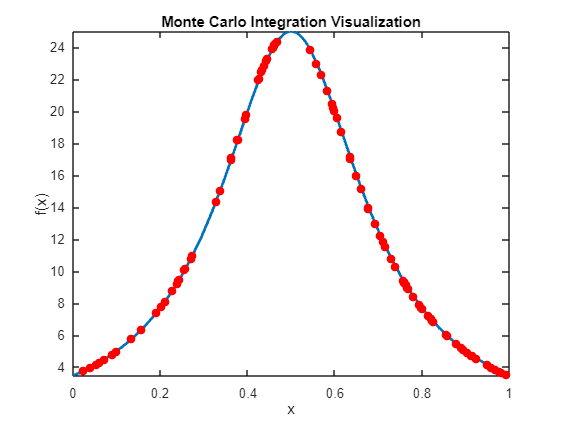


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_1D(fun1, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral2(fun2, a_l, b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:141.679



% 2D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun2,a_l,b_u,N);
toc

Elapsed time is 0.224052 seconds.


disp("2D Monte Carlo Integral:"+monte_value);

2D Monte Carlo Integral:141.6106



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.048283


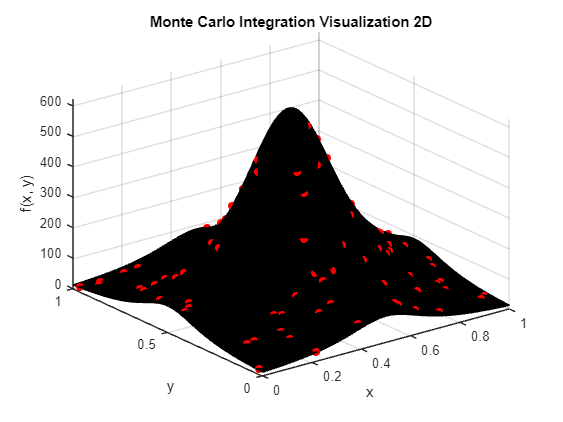


%In order to show the relationsip between each sample and the function
N=100;
monte_carlo_integration_visualization_2D(fun2, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral3(fun3, a_l, b_u,a_l,b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:1686.3909



% 3D Monte-Carlo Integral
tic
monte_value=monte_carlo_integration(fun3,a_l,b_u,N);
toc

Elapsed time is 0.300367 seconds.


disp("3D Monte Carlo Integral:"+monte_value);

3D Monte Carlo Integral:1683.7876



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.15437


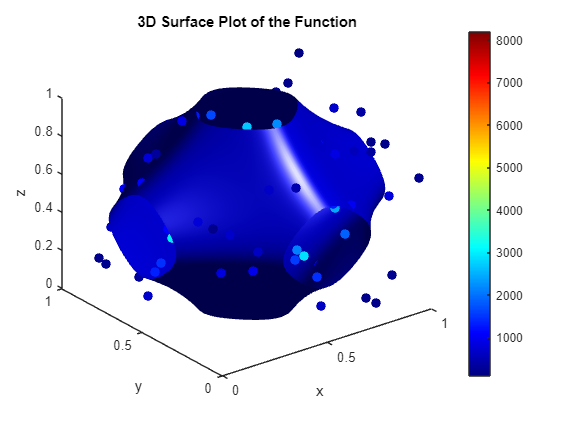


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_3D(fun3, a_l, b_u, N);

### **Function #4 Monte-Carlo**

% Define the limits of integration for each dimension
a = 5;
u = 0.5;

fun1 = @(x) cos(2.*pi.*u + a.*x);
fun2 = @(x, y) cos(2.*pi.*u + a.*x+a.*y);
fun3 = @(x, y, z) cos(2.*pi.*u + a.*x+a.*y+a.*z);



% Define the limits of integration for each dimension,since for all 3
% variables are the same, we can only define the lower bound and upper
% bound.
a_l = 0;
b_u = 1;

%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral(fun1, a_l, b_u);
disp("matlab:"+matlab);

matlab:0.19178



% 1D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun1,a_l,b_u,N);
toc

Elapsed time is 0.102554 seconds.


disp("1D Monte Carlo Integral:"+monte_value);

1D Monte Carlo Integral:0.19217



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100; 
disp("Abserror:"+Abserror);

Abserror:0.20239


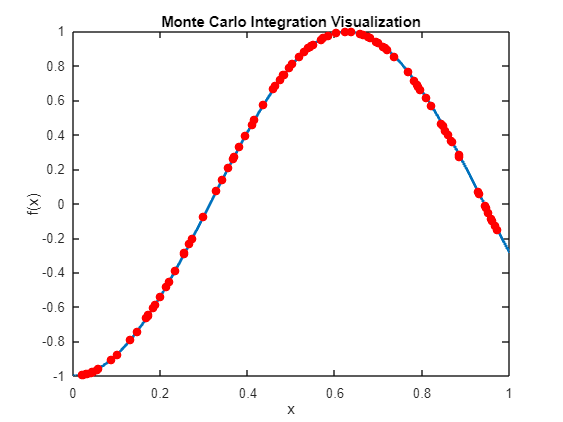


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_1D(fun1, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral2(fun2, a_l, b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:-0.016256



% 2D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun2,a_l,b_u,N);
toc

Elapsed time is 0.105107 seconds.


disp("2D Monte Carlo Integral:"+monte_value);

2D Monte Carlo Integral:-0.015548



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:4.3543


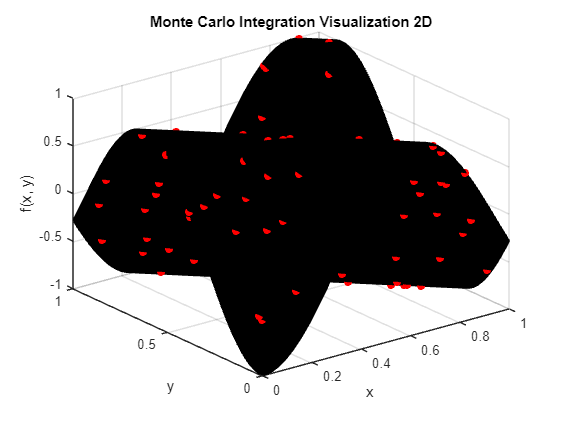


%In order to show the relationsip between each sample and the function
N=100;
monte_carlo_integration_visualization_2D(fun2, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral3(fun3, a_l, b_u,a_l,b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:-0.0047554



% 3D Monte-Carlo Integral
tic
monte_value=monte_carlo_integration(fun3,a_l,b_u,N);
toc

Elapsed time is 0.142891 seconds.


disp("3D Monte Carlo Integral:"+monte_value);

3D Monte Carlo Integral:-0.00425



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:10.6265


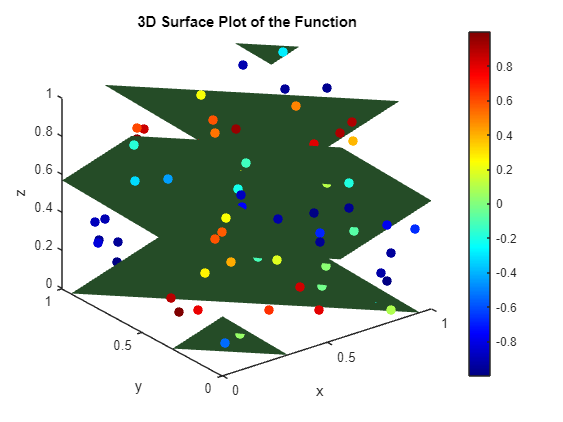


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_3D(fun3, a_l, b_u, N);

### **Function #5 Monte-Carlo**

% Define the limits of integration for each dimension
a = 5;


fun1 = @(x) (abs(4.*x-2)+a)./(1+a);
fun2 = @(x,y) (abs(4.*x-2)+a)./(1+a) .* (abs(4.*y-2)+a)./(1+a);
fun3 = @(x,y,z) (abs(4.*x-2)+a)./(1+a) .* (abs(4.*y-2)+a)./(1+a).* (abs(4.*z-2)+a)./(1+a);



% Define the limits of integration for each dimension,since for all 3
% variables are the same, we can only define the lower bound and upper
% bound.
a_l = 0;
b_u = 1;

%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral(fun1, a_l, b_u);
disp("matlab:"+matlab);

matlab:1



% 1D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun1,a_l,b_u,N);
toc

Elapsed time is 0.121458 seconds.


disp("1D Monte Carlo Integral:"+monte_value);

1D Monte Carlo Integral:1.0001



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100; 
disp("Abserror:"+Abserror);

Abserror:0.014149


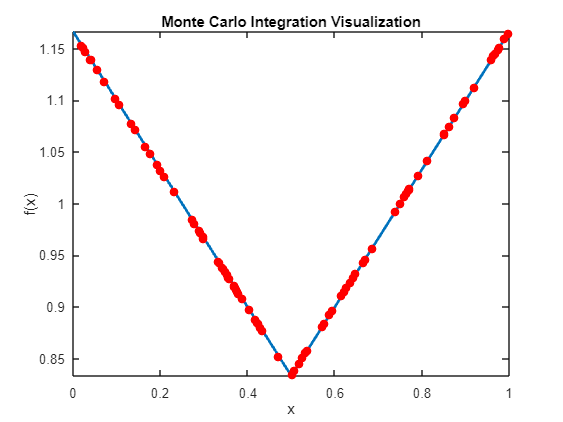


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_1D(fun1, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral2(fun2, a_l, b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:1



% 2D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun2,a_l,b_u,N);
toc

Elapsed time is 0.088652 seconds.


disp("2D Monte Carlo Integral:"+monte_value);

2D Monte Carlo Integral:0.9999



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.0095259


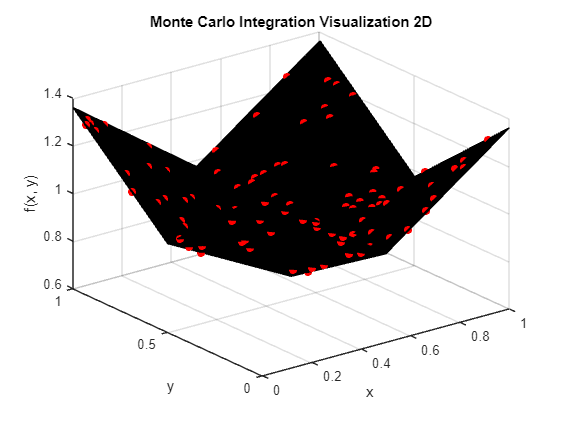


%In order to show the relationsip between each sample and the function
N=100;
monte_carlo_integration_visualization_2D(fun2, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral3(fun3, a_l, b_u,a_l,b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:1



% 3D Monte-Carlo Integral
tic
monte_value=monte_carlo_integration(fun3,a_l,b_u,N);
toc

Elapsed time is 0.127645 seconds.


disp("3D Monte Carlo Integral:"+monte_value);

3D Monte Carlo Integral:1



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.0033476


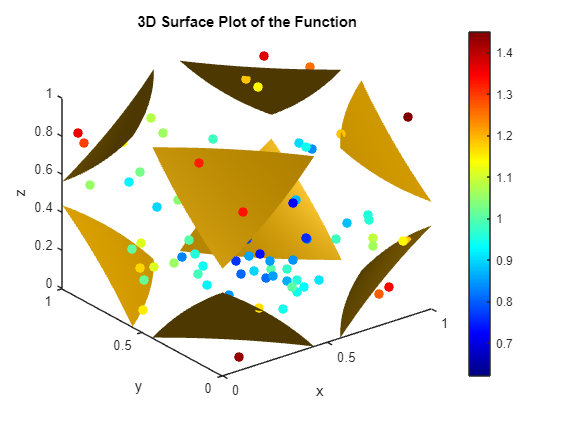


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_3D(fun3, a_l, b_u, N);

### **Function #6 Monte-Carlo**

% Define the limits of integration for each dimension
a = 5;


fun1 = @(x) (1+a*x).^(-2);
fun2 = @(x,y)  (1+a*x+a*y).^(-3);
fun3 = @(x,y,z) (1+a*x+a*y+a*z).^(-4);


% Define the limits of integration for each dimension,since for all 3
% variables are the same, we can only define the lower bound and upper
% bound.
a_l = 0;
b_u = 1;

%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral(fun1, a_l, b_u);
disp("matlab:"+matlab);

matlab:0.16667



% 1D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun1,a_l,b_u,N);
toc

Elapsed time is 0.257893 seconds.


disp("1D Monte Carlo Integral:"+monte_value);

1D Monte Carlo Integral:0.16669



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100; 
disp("Abserror:"+Abserror);

Abserror:0.016293


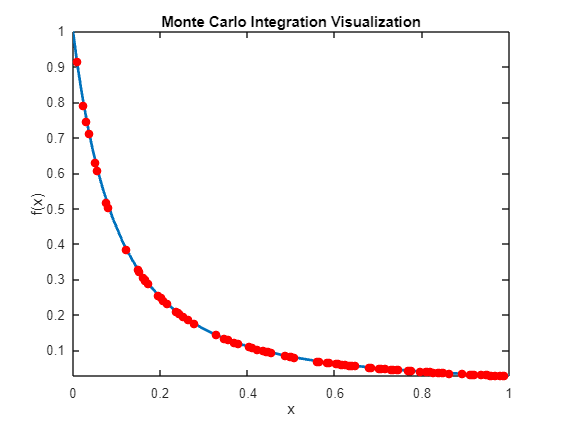


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_1D(fun1, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral2(fun2, a_l, b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:0.015152



% 2D Monte-Carlo Integral
tic
monte_value = monte_carlo_integration(fun2,a_l,b_u,N);
toc

Elapsed time is 0.239887 seconds.


disp("2D Monte Carlo Integral:"+monte_value);

2D Monte Carlo Integral:0.015182



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.1997


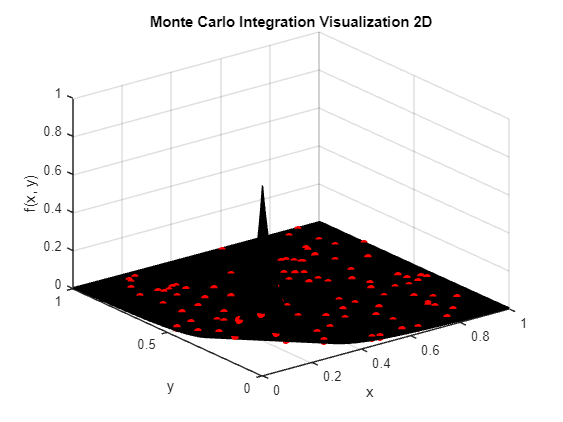


%In order to show the relationsip between each sample and the function
N=100;
monte_carlo_integration_visualization_2D(fun2, a_l, b_u, N);


%Determine the number of samples
N=1000000;

%Use build-in function to calculate the integral
matlab = integral3(fun3, a_l, b_u,a_l,b_u,a_l,b_u);
disp("matlab:"+matlab);

matlab:0.00094697



% 3D Monte-Carlo Integral
tic
monte_value=monte_carlo_integration(fun3,a_l,b_u,N);
toc

Elapsed time is 0.266365 seconds.


disp("3D Monte Carlo Integral:"+monte_value);

3D Monte Carlo Integral:0.00095435



%Calculate the absolute value of the relative error
Abserror = abs(monte_value - matlab) / abs(matlab) * 100;
disp("Abserror:"+Abserror);

Abserror:0.77923


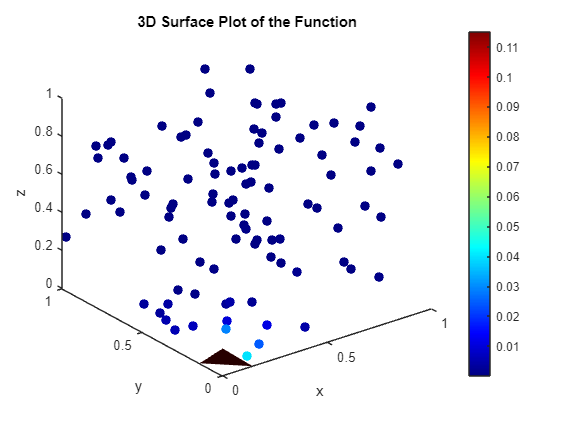


%In order to show the relationsip between each sample and the function
N = 100;
monte_carlo_integration_visualization_3D(fun3, a_l, b_u, N);

## Numerical Integration Algorithm Comparison

### **Function 4**

The number of nodes used for Gauss-Legendre is naturally cubed. The array `N_gl` holds the number of nodes in each dimension for Gauss-Legendre, and gives the equivalent number of nodes for the Monte-Carlo algorithm. Like with the previous sections, the time is recorded and the error is compared to the value found with MatLab's `integral3`.

N_gl = [5 10 50 100 250 300 600]; % Unidimensional number of nodes
N_mc = N_gl.^3; % Number of nodes for Monte-Carlo
u = 0.5;
a = 5;
fun3 = @(x, y, z) cos(2.*pi.*u + a.*x+a.*y+a.*z); % Function 4 is used here
a_x = 0; b_x = 1; % Limits for x
a_y = 0; b_y = 1; % Limits for y
a_z = 0; b_z = 1; % Limits for y
a_l = 0; b_u = 1; % Limits for all 3 (M-C)

value3 = integral3(fun3, a_x, b_x, a_y, b_y, a_z, b_z); % MatLab calculated value for Error

GLError = zeros([1,length(N_gl)]);
MCError = zeros([1,length(N_gl)]);
GLTime = zeros([1,length(N_gl)]);
MCTime = zeros([1,length(N_gl)]);

for i = 1:length(N_gl) % evaluate for each node value
    mcStart = tic;
    value_mc = monte_carlo_integration(fun3, a_l, b_u, N_mc(i));
    MCTime(i) = toc(mcStart);
    MCError(i) = abs(value_mc - value3) / abs(value3) * 100;
    glStart = tic;
    value_GL3 = integral_GL3(fun3,[N_gl(i), N_gl(i), N_gl(i)], a_x, b_x, a_y, b_y, a_z, b_z);
    GLError(i) = abs(value_GL3 - value3) / abs(value3) * 100;
    GLTime(i) = toc(glStart);
    
end
disp(GLError);

    0.0042    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



disp(MCError);

  874.6657   21.9151   15.5572   16.3587    1.3946    0.2569    0.7461



disp(GLTime);

    0.0067    0.0052    0.0179    0.0919    1.4272    2.5558   20.8358



disp(GLTime);

    0.0067    0.0052    0.0179    0.0919    1.4272    2.5558   20.8358



### **Function 3**

The same is done for Function 3.

N_gl = [5 10 50 100 250 300 400 600];
N_mc = N_gl.^3;

% Function 3 is used here
fun3 = @(x, y, z) 1 ./ (a.^(-2) + (x - u).^2) .* 1 ./ (a.^(-2) + (y - u).^2) .* 1 ./ (a.^(-2) + (z - u).^2);

a_x = 0; b_x = 1; % Limits for x
a_y = 0; b_y = 1; % Limits for y
a_z = 0; b_z = 1; % Limits for y
a_l = 0; b_u = 1; % Limits for all 3 (M-C)

value3 = integral3(fun3, a_x, b_x, a_y, b_y, a_z, b_z); % MatLab calculated value for error comparison

GLError = zeros([1,length(N_gl)]);
MCError = zeros([1,length(N_gl)]);
GLTime = zeros([1,length(N_gl)]);
MCTime = zeros([1,length(N_gl)]);

for i = 1:length(N_gl)
    mcStart = tic;
    value_mc = monte_carlo_integration(fun3, a_l, b_u, N_mc(i));
    MCTime(i) = toc(mcStart);
    MCError(i) = abs(value_mc - value3) / abs(value3) * 100;
    glStart = tic;
    value_GL3 = integral_GL3(fun3,[N_gl(i), N_gl(i), N_gl(i)], a_x, b_x, a_y, b_y, a_z, b_z);
    GLError(i) = abs(value_GL3 - value3) / abs(value3) * 100;
    GLTime(i) = toc(glStart);
    
end
disp(GLError);

   11.2088    0.2173    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



disp(MCError);

    2.8651    2.1959    0.4937    0.0413    0.0542    0.0137    0.0034    0.0010



disp(GLTime);

    0.0104    0.0009    0.0675    0.2445    3.8041    6.7257   15.9323   51.9239



disp(GLTime);

    0.0104    0.0009    0.0675    0.2445    3.8041    6.7257   15.9323   51.9239



## Appendix

### Gauss-Legendre Integration

#### Gauss-Legendre Polynomials - Nodes and Weights

function [x, w] = gausslegendre(n, a, b)
% Compute the Gauss-Legendre quadrature nodes and weights on the interval [a, b]
% n: Number of quadrature points
% a, b: Lower and upper limits of integration
% From Gaussian Quadrature and the Eigenvalue Problem - John A. Gubner

    sqrtBeta = sqrt(1./(4-1./ [1:n-1].^2));                   % Beta coefficients 1...n-1 which go in the super and subdiagonal of the matrix.
    % Note: alpha coefficent are all 0, hence they are not explicitly calculated.
    jacobiMatrix = diag(sqrtBeta,1) + diag(sqrtBeta,-1);      % Jacobi Matrix containing the sqrtBeta in super and subdiagonal of the matrix.
    [V, Lambda] = eig(jacobiMatrix);                          % Perform Eigen decomposition of jacobiMatrix.
    [x, i] = sort(diag(Lambda));                              % Genetrate Nodes and Index | Corresponding to the eigen values of the jacobi matrix.
    w = 2 * V(1,i).^2;                                        % Calculate the weights by the Golub-Welsh Algorithm.
    x = (b - a) / 2 * x + (a + b) / 2;                        % Rescales the Nodes for domain [a,b].
    w = (b - a) / 2 * w;                                      % Rescales the Weigths for domain [a,b].
end

#### Gauss-Legendre 1D Integration

function integral_value = integral_GL1(func, num_points, a_x, b_x)
% Compute the 1D integral using Gauss-Legendre quadrature on the interval [a_x, b_x]
% [num_points]: Number of quadrature points
% a_x, b_x:     Lower and upper limits of integration
    
    num_points_x = num_points(1);                              % Extract number of points from array.                                    
 
    [x, w_x] = gausslegendre(num_points_x, a_x, b_x);          % Generate x -> nodes and w_x -> weights for 1D
    

    integral_value = 0;                                        % Initilize integral sum
    for i = 1:num_points_x                                     % Loop from 1 to number of nodes

        integral_value = integral_value + func(x(i)) * w_x(i); % update integral sum <- sum + f(x) * w
    end
end


#### Gauss-Legendre 2D Integration

function integral_value = integral_GL2(func, num_points, a_x, b_x, a_y, b_y)
% Compute the 2D integral using Gauss-Legendre quadrature on the interval [a_x, b_x] X [a_y, b_y]
% [num_points] -> [num_points_x,num_points_y] : Number of quadrature points
% a_x, b_x:     Lower and upper limits of integration for x-axis
% a_y, b_y:     Lower and upper limits of integration for y-axis
    

    num_points_x = num_points(1);                                                     % Extract number of points in X from array.
    num_points_y = num_points(2);                                                     % Extract number of points in Y from array.

    [x, w_x] = gausslegendre(num_points_x, a_x, b_x);                                 % Generate x -> nodes in X and w_x -> weights in X for 2D
    [y, w_y] = gausslegendre(num_points_y, a_y, b_y);                                 % Generate y -> nodes in Y and w_y -> weights in Y for 2D


    integral_value = 0;                                                               % Initilize integral sum
    % Iterations = num_points_x * num_points_y
    for i = 1:num_points_x                                                            % Loop1 from 1 to number of nodes
        for j = 1:num_points_y                                                        % Loop2 from 1 to number of nodes 
                integral_value = integral_value + func(x(i), y(j)) * w_x(i) * w_y(j); % update integral sum <- sum + f(x,y) * w_x * w_y
        end
    end
end

    

#### Gauss-Legendre 3D Integration

function integral_value = integral_GL3(func, num_points, a_x, b_x, a_y, b_y, a_z, b_z)
% Compute the 3D integral using Gauss-Legendre quadrature on the interval [a_x, b_x] X [a_y, b_y] X [a_z, b_z]
% [num_points] -> [num_points_x,num_points_y,num_points_z] : Number of quadrature points
% a_x, b_x:     Lower and upper limits of integration for x-axis
% a_y, b_y:     Lower and upper limits of integration for y-axis
% a_z, b_z:     Lower and upper limits of integration for z-axis
    num_points_x = num_points(1);                                                                      % Extract number of points in X from array.
    num_points_y = num_points(2);                                                                      % Extract number of points in Y from array.
    num_points_z = num_points(3);                                                                      % Extract number of points in Z from array.

    [x, w_x] = gausslegendre(num_points_x, a_x, b_x);                                                  % Generate x -> nodes in X and w_x -> weights in X for 3D
    [y, w_y] = gausslegendre(num_points_y, a_y, b_y);                                                  % Generate y -> nodes in X and w_x -> weights in Y for 3D
    [z, w_z] = gausslegendre(num_points_z, a_z, b_z);                                                  % Generate z -> nodes in X and w_x -> weights in Z for 3D
    
    
    integral_value = 0;                                                                                % Initilize integral sum
    % Iterations = num_points_x * num_points_y * num_points_z 
    for i = 1:num_points_x                                                                             % Loop1 from 1 to number of nodes
        for j = 1:num_points_y                                                                         % Loop2 from 1 to number of nodes 
            for k = 1:num_points_z                                                                     % Loop3 from 1 to number of nodes 
                integral_value = integral_value + func(x(i), y(j), z(k)) * w_x(i) * w_y(j) * w_z(k);   % update integral sum <- sum + f(x,y,z) * w_x * w_y * w_z
            end
        end
    end
end

### Gauss-Legendre Plots

#### Gauss-Legendre** 1D Plot**


function plot_1D( f, lower_limit_x, upper_limit_x)
    x_values = linspace(lower_limit_x, upper_limit_x, 100);
    y_values = f(x_values);

    % Plot the surface
    figure;
    plot(x_values, y_values);
    hold on
    
    % Labeling and title
    xlabel('x');

    zlabel('f(x)');
    title('Function Integrated using Gauss-Legendre - 1D Version');
    hold off
end

#### Gauss-Legendre** 2D Plot**

function plot_2D( f, lower_limit_x, upper_limit_x, lower_limit_y, upper_limit_y)
    [x_values, y_values] = meshgrid(linspace(lower_limit_x, upper_limit_x, 100), linspace(lower_limit_y, upper_limit_y, 100));
    z_values = f(x_values, y_values);

    % Plot the surface
    figure;
    surf(x_values, y_values, z_values);
    hold on
    
    % Labeling and title
    xlabel('x');
    ylabel('y');
    zlabel('f(x, y)');
    title('Function Integrated using Gauss-Legendre - 2D Version');
    hold off
end

#### Gauss-Legendre** 3D Plot**

function plot_3D(f, lower_limit_x, upper_limit_x, lower_limit_y, upper_limit_y, lower_limit_z, upper_limit_z)
    x = linspace(lower_limit_x, upper_limit_x, 100);
    y = linspace(lower_limit_y, upper_limit_y, 100);
    z = linspace(lower_limit_z, upper_limit_z, 100);
 
    [X, Y, Z] = meshgrid(x, y, z);
    
    % Generate slicing planes
    xslices = linspace(lower_limit_x, upper_limit_x, 3);
    yslices = linspace(lower_limit_y, upper_limit_y, 3); 
    zslices = linspace(lower_limit_z, upper_limit_z, 3); 
    
    % Plot the slices
    figure;
    for i = 1:length(xslices)
        for j = 1:length(yslices)
            for k = 1:length(zslices)
                slice(X, Y, Z, f(X, Y, Z), xslices(i), yslices(j), zslices(k));
                hold on; % To overlay multiple slices
            end
        end
    end
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Function Integrated using Gauss-Legendre - 3D Version');
    colorbar;
    clim([min(f(X, Y, Z), [], 'all'), max(f(X, Y, Z), [], 'all')]);
    cbar = colorbar;
    cbar.Label.String = 'f(x, y, z)';
    hold off; 
end


### **Monte-Carlo Based Integration**

function value = monte_carlo_integration(f,a,b,N)
    %f is the function to be integrated
    %a is lower bound
    %b is upper bound
    %N is the number of samples

    sum = 0; % Initialize the sum
    num_vars = nargin(f); %Determine the dimension of the function
    switch num_vars

        case 1

            X=rand(1,N)*(b-a)+a; %Randomly generate the points from lower bound to upper bound

            %Update the value of the sum
            for i = 1:N
                k = f(X(i));
                sum = sum + k; 
            end

            value = (sum*(b-a))/N; %Use the formula (volume/Total number)*Summation
            
            



        case 2
            X=rand(1,N)*(b-a)+a; %Randomly generate the points from lower bound to upper bound
            Y=rand(1,N)*(b-a)+a; %Randomly generate the points from lower bound to upper bound
            
            %Update the value of the sum
            for i = 1:N
                k = f(X(i),Y(i));
                sum = sum + k;
            end

            value = (sum*(b-a)*(b-a))/N; %Use the formula (volume/Total number)*Summation
            
           


        case 3
            X=rand(1,N)*(b-a)+a; %Randomly generate the points from lower bound to upper bound
            Y=rand(1,N)*(b-a)+a; %Randomly generate the points from lower bound to upper bound
            Z=rand(1,N)*(b-a)+a; %Randomly generate the points from lower bound to upper bound
            
             %Update the value of the sum
            for i = 1:N
                k = f(X(i),Y(i),Z(i));
                sum = sum + k;
            end

            value = (sum*(b-a)*(b-a)*(b-a))/N; %Use the formula (volume/Total number)*Summation
            



        otherwise
            disp("Unsupported number of variables!");
    end
end

### **Monte-Carlo Plots**

#### **Monte-Carlo 1D Plot**

function monte_carlo_integration_visualization_1D(f, a, b, N)
    % Generate the function graph and the random sampling points within the interval [a, b] for each variable
    X = rand(1, N) * (b - a) + a;
    
    % Calculate function values at the sampling points
    Y = f(X);
    
    % Plot the function
    figure;
    fplot(f, [a, b], 'LineWidth', 2); % Plot the function
    hold on;
    
    % Plot the sampled points on the function curve
    plot(X, Y, 'ro', 'MarkerFaceColor', 'r'); % Plot the samples
    
    % Title and labels
    title('Monte Carlo Integration Visualization');
    xlabel('x');
    ylabel('f(x)');
    
    % Hold off to release the plot
    hold off;
end


#### **Monte-Carlo 2D Plot**

function monte_carlo_integration_visualization_2D(f, a, b, N)
    % Generate the function graph and the random sampling points within the interval [a, b] for each variable
    X_rand = rand(1, N) * (b - a) + a;
    Y_rand = rand(1, N) * (b - a) + a;
    
    % Calculate function values at the sampling points
    Z_rand = f(X_rand, Y_rand);
    
    % Plot the function surface
    figure;
    x = linspace(a, b, 1000);
    y = linspace(a, b, 1000);
    [X, Y] = meshgrid(x, y);
    Z = f(X, Y);
    surf(X, Y, Z);
    title('3D Surface Plot of the Function');
    xlabel('x');
    ylabel('y');
    zlabel('f(x, y)');
    hold on;
    
    % Plot the sampled points on the function surface
    scatter3(X_rand, Y_rand, Z_rand, 'filled', 'MarkerFaceColor', 'r'); % Plot the samples
    
    % Set title and labels
    title('Monte Carlo Integration Visualization 2D');
    xlabel('x');
    ylabel('y');
    zlabel('f(x, y)');
    
    hold off;
end


#### **Monte-Carlo 3D plot**

function monte_carlo_integration_visualization_3D(f, a, b, N)
    % Generate the function graph and the random sampling points within the interval [a, b] for each variable
    X_rand = rand(1, N) * (b - a) + a;
    Y_rand = rand(1, N) * (b - a) + a;
    Z_rand = rand(1, N) * (b - a) + a;
    W_rand = f(X_rand, Y_rand, Z_rand);

    % Plot the function surface
    figure;
    x = linspace(a, b, 100);
    y = linspace(a, b, 100);
    z = linspace(a, b, 100);
    [X, Y, Z] = meshgrid(x, y, z);
    W = f(X, Y, Z);
    isosurface(X, Y, Z, W);
    title('3D Surface Plot of the Function');
    xlabel('x');
    ylabel('y');
    zlabel('z');
    hold on;
    
    % Plot sampled points with color representing the fourth dimension (W)
    scatter3(X_rand, Y_rand, Z_rand, 50, W_rand, 'filled');
    colormap(jet);
    colorbar;
    
    hold off;
end


### **Smolyak Sparse Grids (Extra)**

#### **Smolyak Sparse Grids**

function A = genSets(mu, d)
%   generate sets of CGL points unidimensional
%   max number of pts would be d + mu: lowest i combo is 1 + i = d + mu
    i = d + mu - 1;
    A = cell(1, i); % creates a i x i
    A{1} = cglnodes(1);
    A{2} = [-1;1];

    for idx = 3:i
        prevSet = cglnodes(2^(idx-2) + 1);
        curSet = cglnodes(2^(idx-1) + 1);
        A{idx} = setdiff(curSet, prevSet);
    end

end

function [sgPoints] = tensorCombo(A, d)
%   A is the cell with the sets you want to combine, in order of dimensions
%   A{1} = x sets, A{2} = y sets, A{3} = z sets
    n = length(A{1});
    m = length(A{2});
    if (d == 2)
        l = 1;
    else
        l = length(A{3});
    end
    
    sgPoints = cell(n*m*l,1);
    idx = 1;

    for i = 1:l
        for j = 1:m
            for k = 1:n
                if (d == 2)
                    sgPoints{idx} = [A{1}(k) A{2}(j)];
                else
                    sgPoints{idx} = [A{1}(k) A{2}(j) A{3}(i)];
                end
                idx = idx + 1;
            end
        end
    end
    sgPoints = cell2mat(sgPoints);
end


function S = chooseSets(A, I)
%   A is the cell with the unidimensional point sets
%   I is a vector with the i_1, i_2, ... i_n indices
    d = length(I);
    S = {};
    for i = 1:d
        S = [S; A{I(i)}];
    end

end


function x = cglnodes(N) 
% From Appendix A of Judd. K.-L. et al. (2014)
    if (N == 1)
        x = 0;
        return;
    end
    x = -cos(pi*(0:N-1)/(N-1))';
end

function I = findIs(mu, d)
%   the largest value any can take for I is mu + 1
%   to satisfy d ≤ sum(i_n) ≤ d + mu
    if (d == 2)
        l = 1;
    else
        l = mu + 1;
    end
    
    I = [];

    for i = 1:l
        for j = 1:mu + d
            for k = 1:mu + d
                iSums = i + j + k;
                if (iSums >= d) && (iSums <= mu + d)
                    % satisfies condition
                    I = [I; k j i];
                end
            end
        end
    end
    
    if (d == 2)
        I = I(:, 1:2);
    end
end

function S = smolyakPoints(mu, dim)
    mu = mu + 1;
    A = genSets(mu,dim);
    I = findIs(mu,dim);
    
    for i = 1:size(I, 1)
        curSets = chooseSets(A, I(i, :));
        StoAppend = tensorCombo(curSets, dim);
        if (i == 1)
        S = StoAppend;
        else
        S = [S; StoAppend];
        end
    

    end
end

####  **Smolyak Sparse Grids - Graphs**

function plotSmolyak2D()

muRange = 2:5;
for i = 1:4
    subplot(2,2,i);
    s = smolyakPoints(muRange(i), 2);

    scatter(s(:,1), s(:,2), 25, 'filled'); 
    title(sprintf('mu = %d', muRange(i)));
end

end

function plotSmolyak3D()

muRange = 2:5;
for i = 1:4
    subplot(2,2,i);
    s = smolyakPoints(muRange(i), 3);

    scatter3(s(:,1), s(:,2), s(:,3), 25, 'filled'); 
    title(sprintf('mu = %d', muRange(i)));
end

end